# Sample 8-6

## 離散コサイン変換

KLT との関係

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete cosine transform

Relation to KLT

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 次元 $M$ の設定

(Setting of dimension $M$)

nPoints = 4;

### 原画像の読込と表示

(Read and display an image)

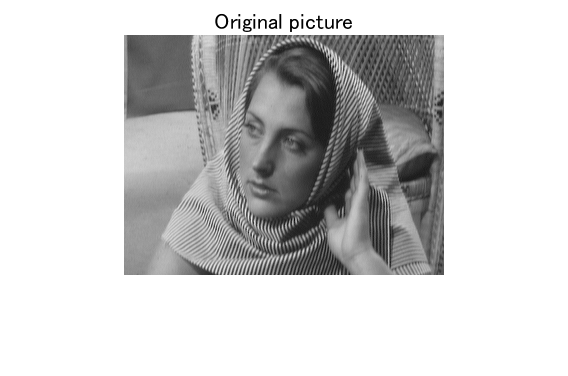

V = rgb2gray(imread('data/barbaraFaceRgb.tif'));
figure(1)
imshow(V)
title('Original picture')

### $M$次元ベクトル集合の抽出

(Extraction of a set of $M$-D vectors)

$M$点の水平方向に連続する画素値をベクトルとして抽出。(Extracts the values of successive horizontal pixels as an $M$-D vector.)

nPixels = numel(V);
setOfX = reshape(V.', nPoints, nPixels/nPoints);

###  変換前の散布図

(Scatter plot before transform)

標本分散共分散行列と相関係数 (Sample covariance matrix and correlation coefficient)

Sxx = cov(double(setOfX.'))

Sxx = 	1.0e+03 *

    2.2547    1.8973    1.7039    1.8259
    1.8973    2.2303    1.8933    1.6928
    1.7039    1.8933    2.2357    1.8829
    1.8259    1.6928    1.8829    2.2109


Rxx = corrcoef(double(setOfX.'))

Rxx =     1.0000    0.8461    0.7589    0.8178
    0.8461    1.0000    0.8479    0.7623
    0.7589    0.8479    1.0000    0.8469
    0.8178    0.7623    0.8469    1.0000


### カル―ネンレーべ(K-L)変換

(Karuhen Loeve transform)

分散共分散行列の固有値分解(Eigenvalue decomposition of the variance-covariance matrix)

- 
$$\mathbf{\Sigma}_{\mathrm{xx}}=\mathbf{\Phi}^T\mathbf{\Lambda}\mathbf{\Phi}$$


[B,D] = eig(Sxx);

固有値のソート (Sorting the eigen valuess)

[~,I] = sort(diag(D));

固有ベクトルを並び換え (Reordering eigenvectors)

B = B(:,nPoints-I+1);

基底ベクトルの表示 (Display the basis vectors)

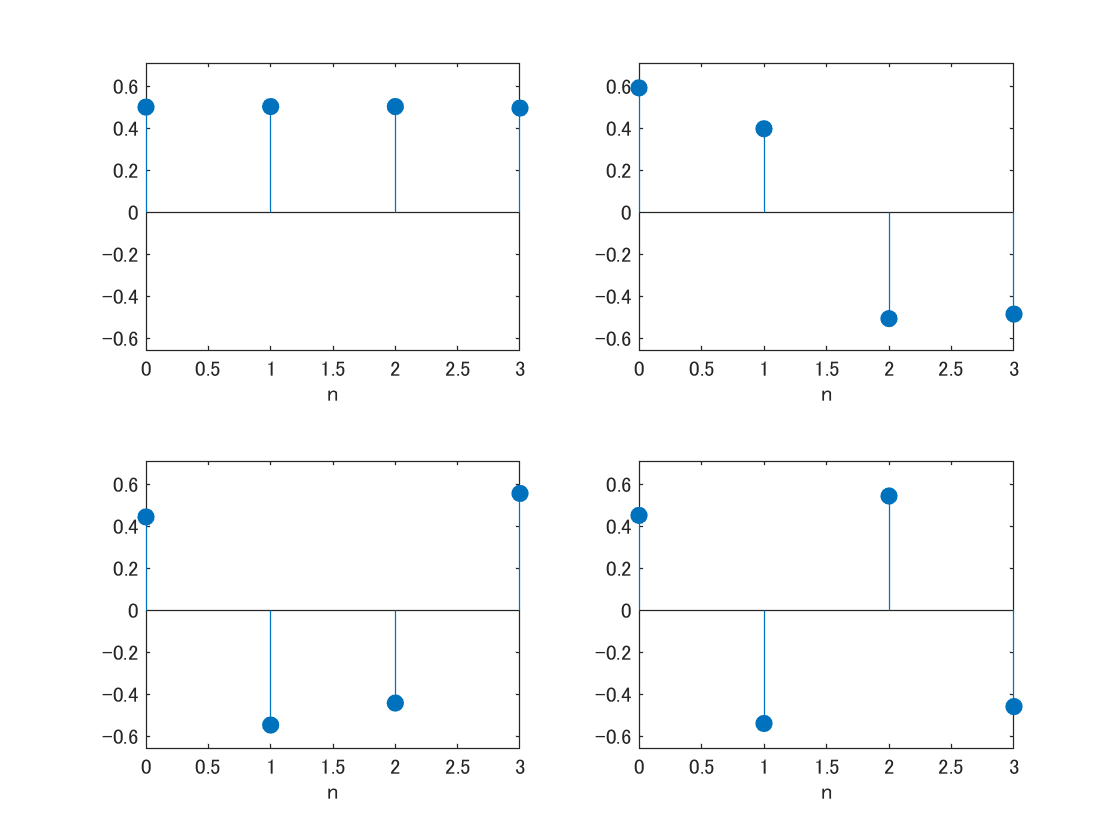

figure(2)
for idx = 1:nPoints
    subplot(ceil(nPoints/2),2,idx);
    stem(0:nPoints-1,B(:,idx),'filled');
    ax = gca;
    ax.YLim = 1.2*[min(B(:)) max(B(:))];
    xlabel('n')
end

K-L 変換 (K-L transform)

Phi = B.';
setOfY = Phi * double(setOfX);

###  変換前後の散布図

(Scatter plots before and after transform)

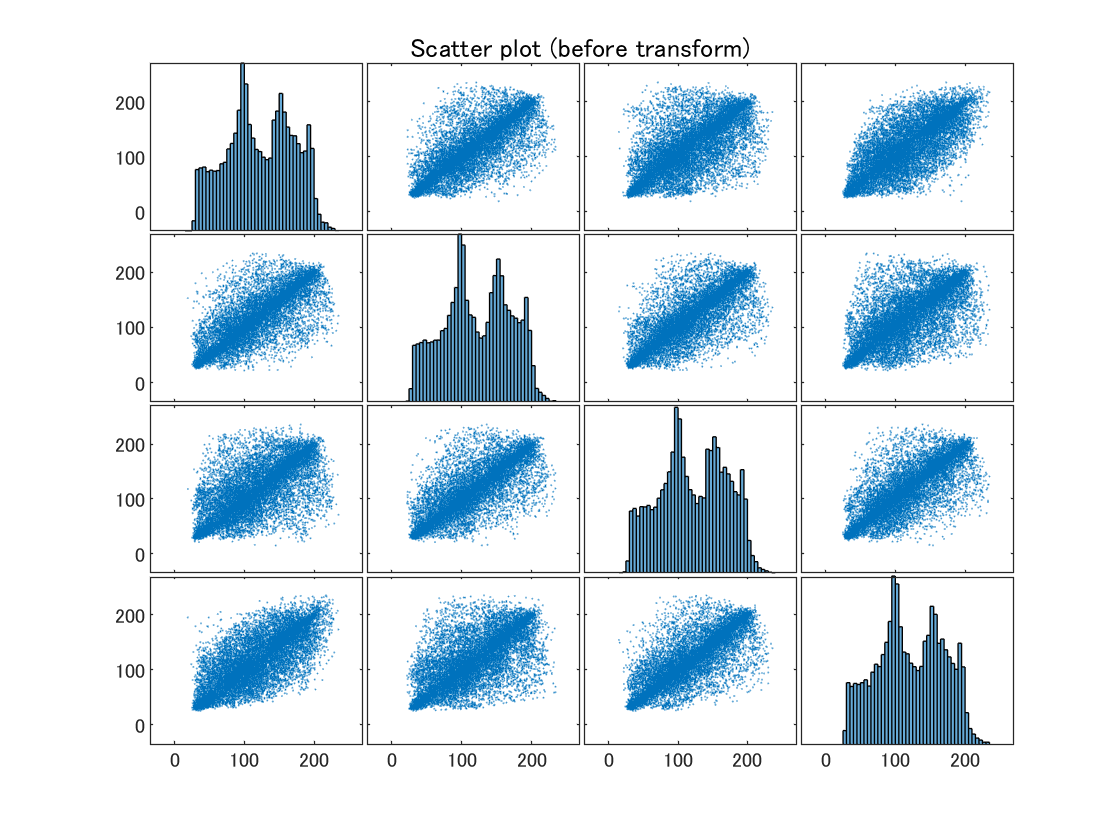

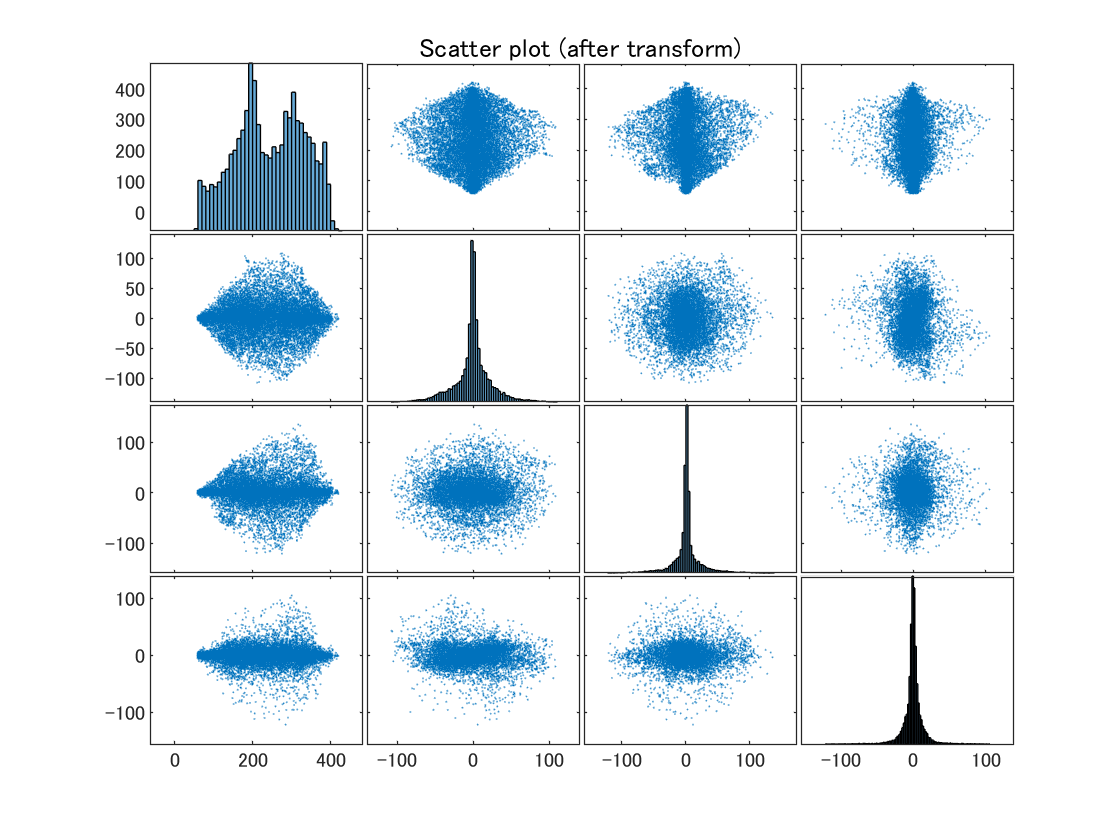

if nPoints == 2
    figure(3)
    scatter(setOfX(1,:),setOfX(2,:),'.')
    axis square
    xlabel('x_0')
    ylabel('x_1')
    title('Scatter plot (before transform)')
    figure(4)
    scatter(setOfY(1,:),setOfY(2,:),'.')
    axis square
    xlabel('y_0')
    ylabel('y_1')
    title('Scatter plot (after transform)')
else
    figure(3)
    plotmatrix(setOfX.','.')
    title('Scatter plot (before transform)')
    figure(4)
    plotmatrix(setOfY.','.')
    title('Scatter plot (after transform)')
end

標本分散共分散行列と相関係数 (Sample covariance matrix and correlation coefficient)

Cyy = cov(double(setOfY.'))

Cyy = 	1.0e+03 *

    7.6812    0.0000   -0.0000    0.0000
    0.0000    0.5687   -0.0000    0.0000
   -0.0000   -0.0000    0.5031   -0.0000
    0.0000    0.0000   -0.0000    0.1786


Ryy = corrcoef(double(setOfY.'))

Ryy =     1.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000


変換後の分散共分散行列と相関係数の非対角成分が0となり、無相関となる。(The non-diagonal components of the sample covariance matrix and correlation coefficient after the transform is zero. That is, the coefficients become uncorrelated.)

### AR(1)モデルのKLT

(KLT of AR(1) model)

- AR(1): the 1-st order autoregressive model

% Correlation coefficient |ρ|<1
rho = 0.999; 

% Covariance matrix
sigma = 1;
Sxx = sigma^2*toeplitz(power(rho,0:nPoints-1))

Sxx =     1.0000    0.9990    0.9980    0.9970
    0.9990    1.0000    0.9990    0.9980
    0.9980    0.9990    1.0000    0.9990
    0.9970    0.9980    0.9990    1.0000


カル―ネンレーべ(K-L)変換 (Karuhen Loeve transform)

[B,D] = eig(Sxx);
[~,I] = sort(diag(D));
B = B(:,nPoints-I+1);

基底ベクトルの表示 (Display the basis vectors)

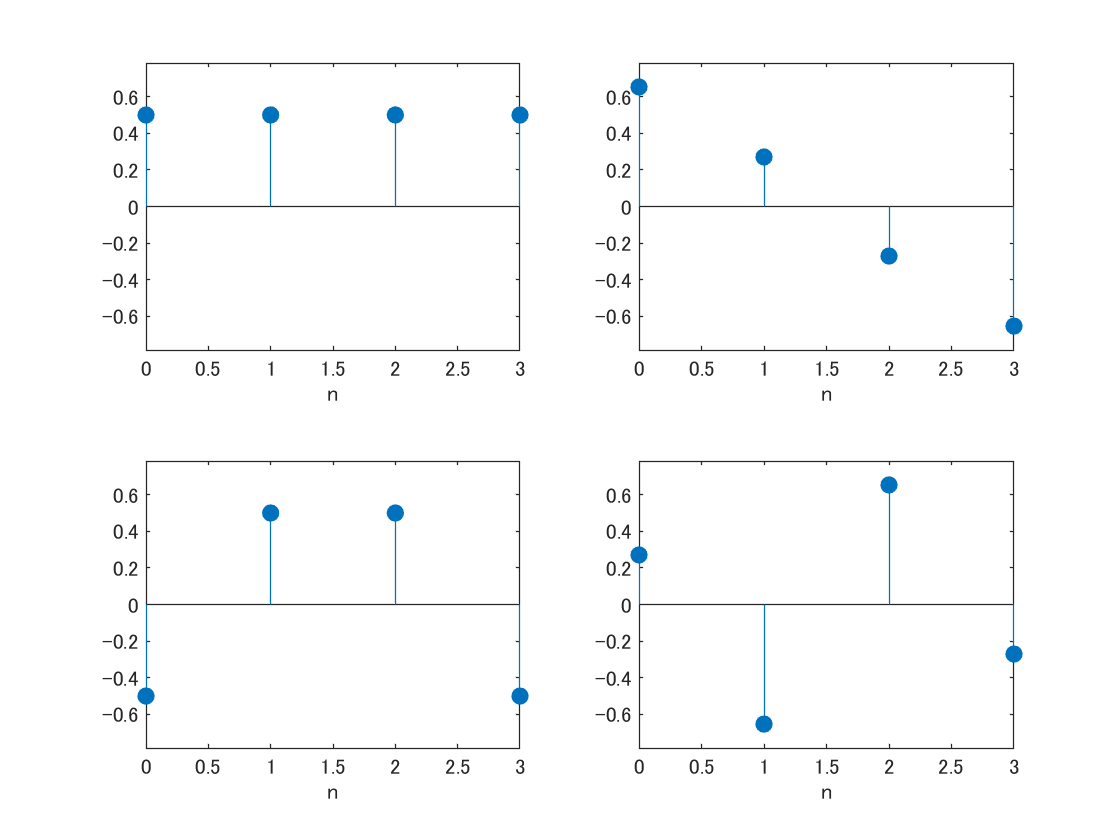

figure(5)
for idx = 1:nPoints
    subplot(ceil(nPoints/2),2,idx);
    stem(0:nPoints-1,B(:,idx),'filled');
    ax = gca;
    ax.YLim = 1.2*[min(B(:)) max(B(:))];
    xlabel('n')
end

## DCT 行列

(DCT matrix)

C = dctmtx(nPoints);
B = C.';

基底ベクトルの表示 (Display the basis vectors)

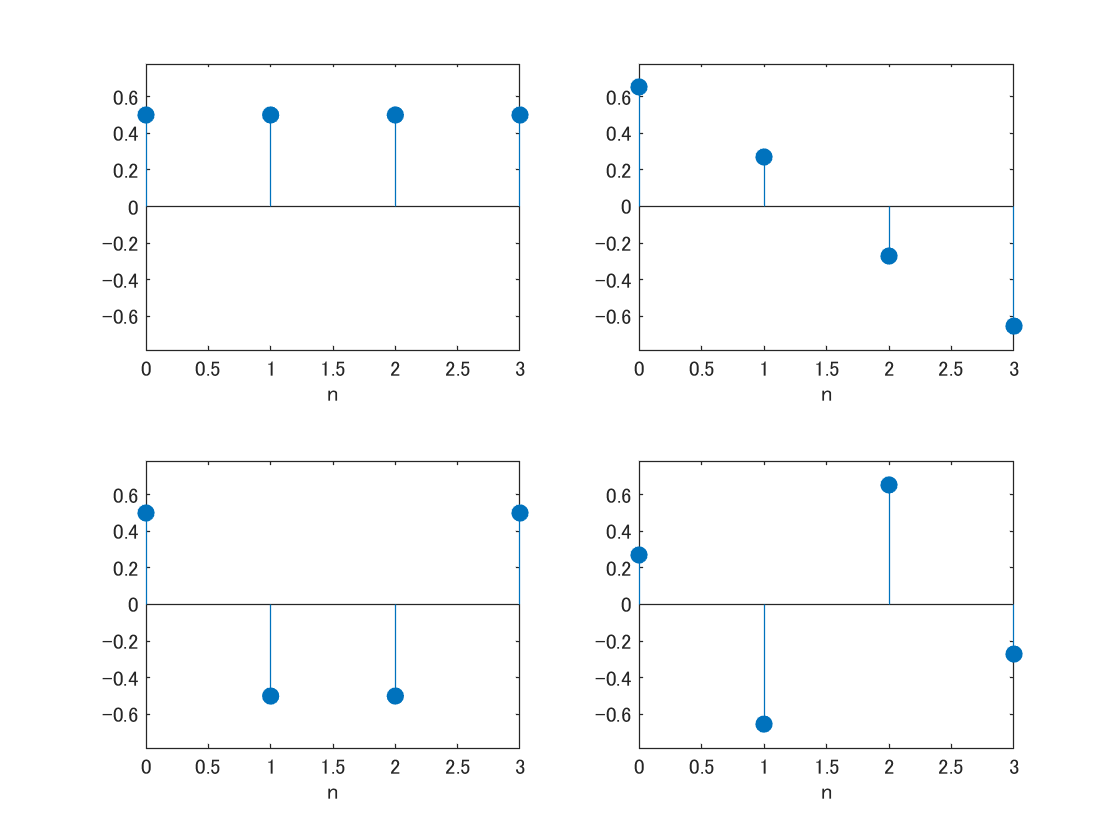

figure(6)
for idx = 1:nPoints
    subplot(ceil(nPoints/2),2,idx);
    stem(0:nPoints-1,B(:,idx),'filled');
    ax = gca;
    ax.YLim = 1.2*[min(B(:)) max(B(:))];
    xlabel('n')
end

相関係数$\rho\rightarrow 1$のAR(1)モデルに対するKLT行列は極限でDCT行列に収束する。(The KLT matrix for the AR(1) model with correlation coefficient $\rho\rightarrow 1$converges to the DCT matrix in the limit.)

© Copyright, Shogo MURAMATSU, All rights reserved.